format long

% ----- ----- ----- ----- ----- ----- CONSTANTS ----- ----- ----- ----- ----- -----
resolution = 1;
bridge_length = 1200;
train_support_tolerance = 1;
relative_load_positions = [0,176,340,516,680,856];
% ----- ----- ----- ----- ----- ----- INITIALIZE VARS ----- ----- ----- ----- ----- -----
startpt = train_support_tolerance; % first x-val of envelope
endpt = bridge_length; % last x-val of envelope
diagramvec = startpt:resolution:endpt; % all x-vals of envelope
diagramlen = length(diagramvec); % number of x-vals of envelope
SFE = zeros(1,diagramlen); % initial SFE y-vals
BME = zeros(1,diagramlen); % initial BME y-vals
% ----- ----- ----- ----- ----- ----- LOAD CASE 2: BASE CASE ----- ----- ----- ----- ----- -----
train_load_case_2_base = 452;
factor_heavier = 1.3481481481481481481481481481;
freight_load_case_2_base = train_load_case_2_base/(2+factor_heavier);
train_loads_case_2_base = [0,-freight_load_case_2_base/2,-freight_load_case_2_base/2,-freight_load_case_2_base/2,-freight_load_case_2_base/2,-factor_heavier*freight_load_case_2_base/2,-factor_heavier*freight_load_case_2_base/2,0];
% ----- ----- ----- ----- ----- ----- LOAD CASE 2: SUBSEQUENT CASES ----- ----- ----- ----- ----- -----
train_load_case_2_sub = 600;
freight_load_case_2_sub = train_load_case_2_sub/(3.585);
heavy_freight = freight_load_case_2_sub*1.1;
light_freight = freight_load_case_2_sub;
locomotive = freight_load_case_2_sub * 1.485;
train_loads_case_2_sub = [0,-heavy_freight/2,-heavy_freight/2,-light_freight/2,-light_freight/2,-locomotive/2,-locomotive/2,0];
% ----- ----- ----- ----- ----- ----- LOAD CASE 1 ----- ----- ----- ----- ----- -----
train_load_case_1 = 400;
freight_load_case_1 = train_load_case_1/3;
train_loads_case_1 = [0,-freight_load_case_1/2,-freight_load_case_1/2,-freight_load_case_1/2,-freight_load_case_1/2,-freight_load_case_1/2,-freight_load_case_1/2,0];
disp("----- ----- ----- ----- ----- -----")

----- ----- ----- ----- ----- -----


% ----- ----- ----- ----- ----- ----- LOAD CASE USED ----- ----- ----- ----- ----- -----
train_loads = train_loads_case_1

train_loads =                    0 -66.666666666666671 -66.666666666666671 -66.666666666666671 -66.666666666666671 -66.666666666666671 -66.666666666666671                   0


train_load = train_load_case_1

train_load =    400


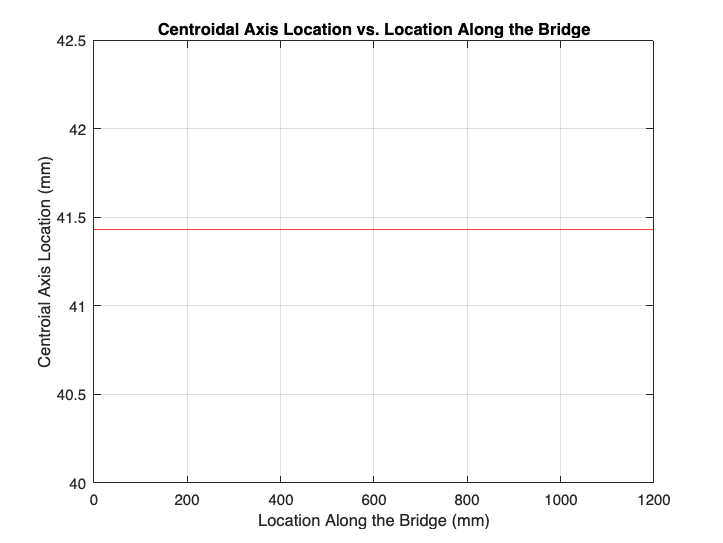

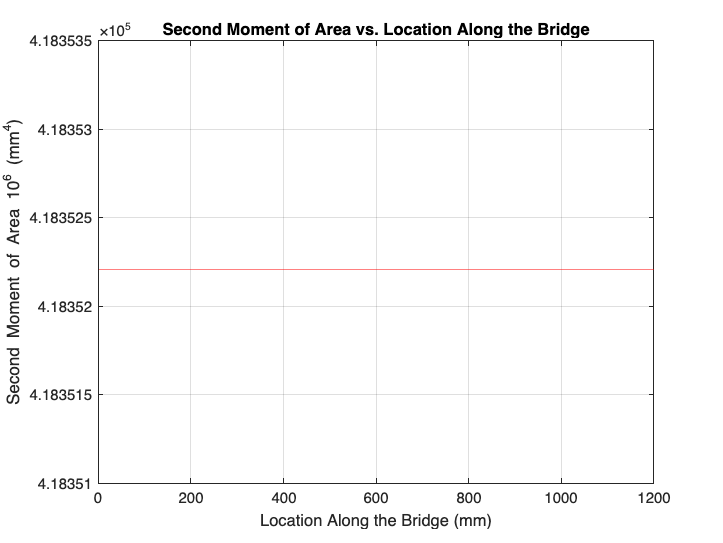

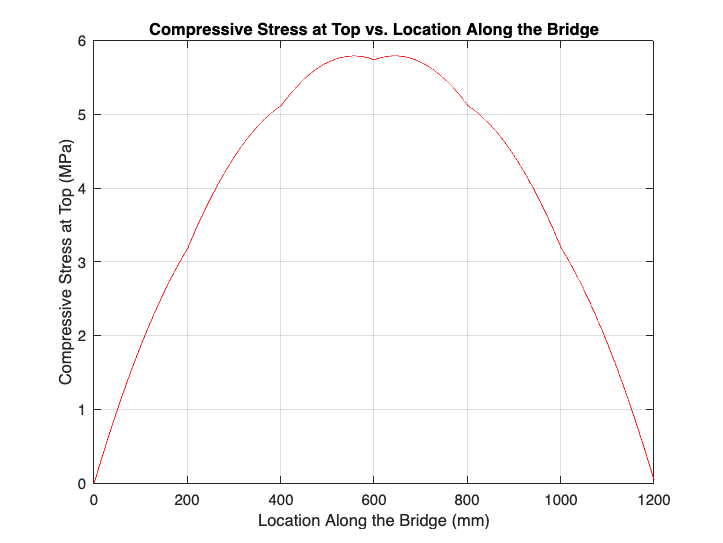

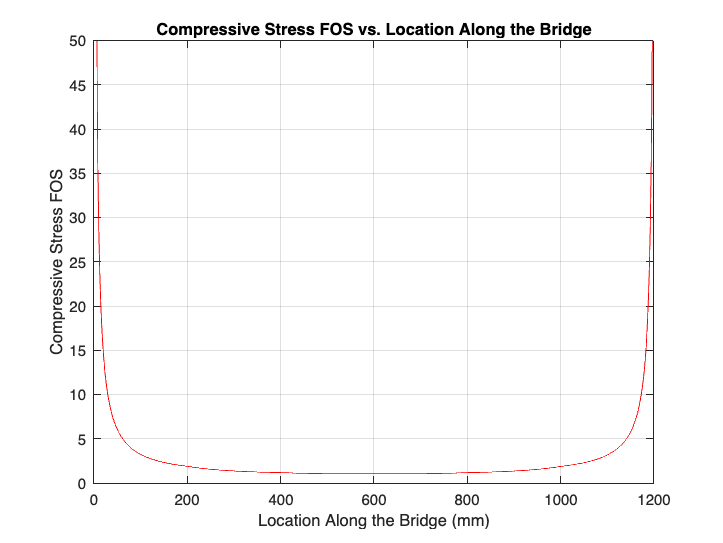

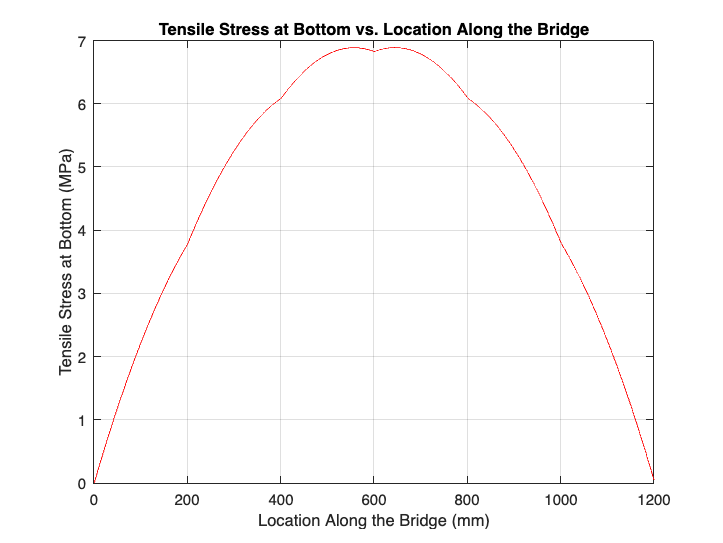

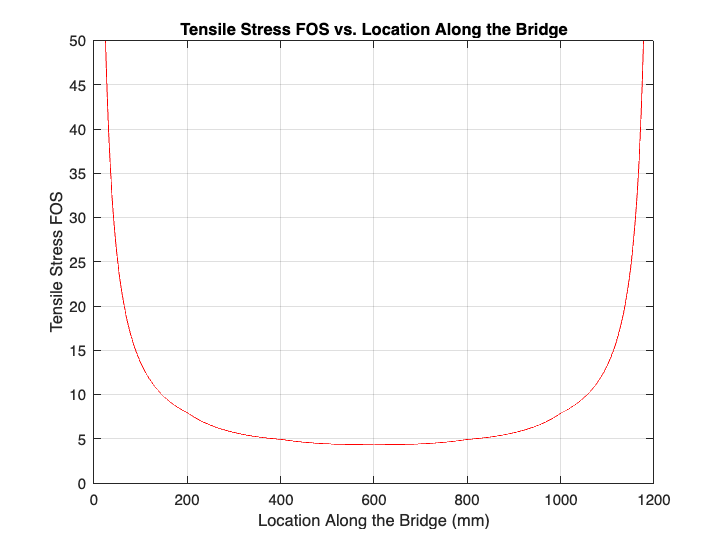

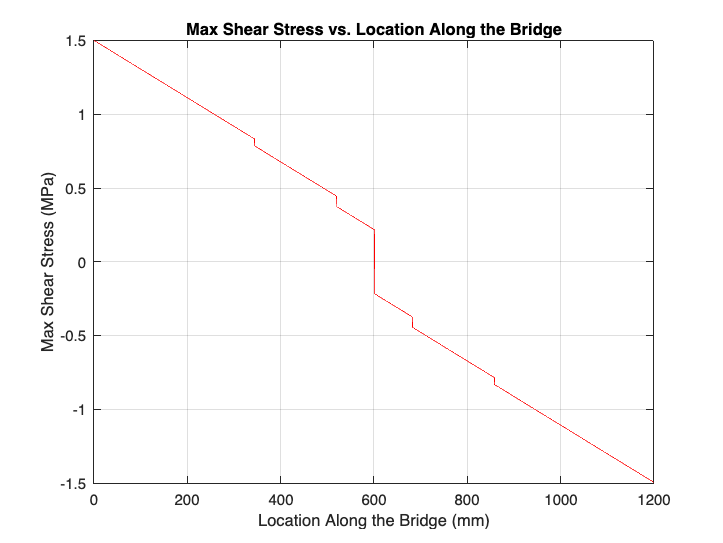

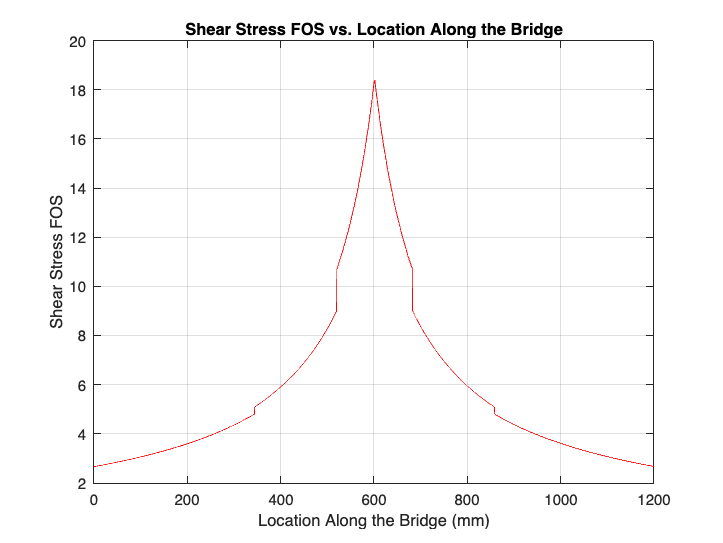

% ----- ----- ----- ----- ----- ----- SHEAR FORCE ENVELOPE ----- ----- ----- ----- ----- -----
[SFE,max_SF_at]= makeSFE(SFE,startpt,resolution,bridge_length,relative_load_positions,train_support_tolerance,train_loads,train_load,diagramvec,diagramlen);
% [SFE,max_SF_at]= makeSFE(SFE,startpt,resolution,bridge_length,relative_load_positions,train_support_tolerance,flip(train_loads),train_load,diagramvec,diagramlen);
% ----- ----- ----- ----- ----- ----- BENDING MOMENT ENVELOPE ----- ----- ----- ----- ----- -----
[BME,max_BM_at] = makeBME(BME,startpt,resolution,bridge_length,relative_load_positions,train_support_tolerance,train_loads,train_load,diagramvec,diagramlen);
% ----- ----- ----- ----- ----- ----- SFD/BMD FOR TRAIN @ MAX SF ----- ----- ----- ----- ----- -----
mySFD = SFD(relative_load_positions+max_SF_at,train_loads,diagramvec,diagramlen,bridge_length,train_load);
myBMD = BMD(diagramvec,mySFD);
% ----- ----- ----- ----- ----- ----- SFD/BMD FOR TRAIN @ MAX BM ----- ----- ----- ----- ----- -----
mySFD = SFD(relative_load_positions+max_BM_at,train_loads,diagramvec,diagramlen,bridge_length,train_load);
myBMD = BMD(diagramvec,mySFD);

% ----- ----- ----- ----- ----- ----- MAKING THE ENVELOPES ----- ----- ----- ----- ----- -----
function [SFE,dis_at_max_SF] = makeSFE(SFE,startpt,resolution,bridge_length,relative_load_positions,train_support_tolerance,train_loads,train_load,diagramvec,diagramlen)
    dis_at_max_SF = -1;
    max_SF = -1;
    for train_pos = startpt:resolution:bridge_length-relative_load_positions(end)-train_support_tolerance
        loads_at = relative_load_positions+train_pos;
        tempSFD = SFD(loads_at,train_loads,diagramvec,diagramlen,bridge_length,train_load);
        
        for datapt = 1:diagramlen
            if (abs(tempSFD(datapt))>abs(max_SF))
                dis_at_max_SF = train_pos;
                max_SF = abs(tempSFD(datapt));
            end
            if (abs(tempSFD(datapt))>abs(SFE(datapt)))
                SFE(datapt) = tempSFD(datapt);
            end
        end   
    end
end
function [BME,dis_at_max_BM] = makeBME(BME,startpt,resolution,bridge_length,relative_load_positions,train_support_tolerance,train_loads,train_load,diagramvec,diagramlen)
    dis_at_max_BM = -1;
    max_BM = -1;
    for train_pos = startpt:resolution:bridge_length-relative_load_positions(end)-train_support_tolerance
        loads_at = relative_load_positions+train_pos;
        
        tempSFD = SFD(loads_at,train_loads,diagramvec,diagramlen,bridge_length,train_load);
        tempBMD = BMD(diagramvec,tempSFD);
        
        for datapt = 1:diagramlen
            if (abs(tempBMD(datapt))>abs(max_BM))
                dis_at_max_BM = train_pos;
                max_BM = abs(tempBMD(datapt));
            end
            if (abs(tempBMD(datapt))>abs(BME(datapt)))
                BME(datapt) = tempBMD(datapt);
            end
        end   
    end
end
% ----- ----- ----- ----- ----- ----- RXN FORCES AT SUPPORTS ----- ----- ----- ----- ----- -----
function result = right_support_reaction(train_loads,bridge_length,loads_at)
    result = -(sum(loads_at.*train_loads(2:7)))/bridge_length;
end
function result = left_support_reaction(right_support,train_load)
    result = train_load - right_support;
end
% ----- ----- ----- ----- ----- ----- MAKE THE DIAGRAMS ----- ----- ----- ----- ----- -----
function SFD = SFD(loads_at,train_loads,diagramvec,diagramlen,bridge_length,train_load)
    train_loads(end) = right_support_reaction(train_loads,bridge_length,loads_at);
    train_loads(1) = left_support_reaction(train_loads(end),train_load);
    
    loads_at = [0,loads_at];
    loads_at = [loads_at,bridge_length];
    
    curr_shear = train_loads(1);
    cur_load = 2;
    SFD_index = 1;

    SFD = ones(1,diagramlen);
    for x = diagramvec
        SFD(SFD_index) = curr_shear;
        SFD_index=SFD_index+1;
        if(x>loads_at(cur_load))
            curr_shear = curr_shear+train_loads(cur_load);
            cur_load=cur_load+1;
        end
    end
end
function BMD = BMD(diagramvec,SFD)
    BMD = cumtrapz(diagramvec,SFD);
end

% ----------------------properties calculations ------------------------

cross_section = [
    0 0 100 1.27;
    10 1.27 6.27 1.27;
    83.73 1.27 6.27 1.27;
    10 2.54 1.27 73.73;
    88.73 2.54 1.27 73.73;
    11.27 75 77.46 1.27
];
x = 1:1200;

use_envolope = true;
shear_force_func = [];
bending_moment_func = [];
if use_envolope
    shear_force_func = [SFE];
    bending_moment_func = [BME];
else
    shear_force_func = [mySFD];
    bending_moment_func = [myBMD];
end

centroidal_axes = zeros(size(x));
second_moment_of_areas = zeros(size(x));
compressive_stresses = zeros(size(x));
compressive_stress_FOS = zeros(size(x));
tensile_stresses = zeros(size(x));
tensile_stress_FOS = zeros(size(x));
shear_stresses = zeros(size(x));
shear_stress_FOS = zeros(size(x));
glue_stresses = zeros(size(x));
glue_stress_FOS = zeros(size(x));
case_1_crit_stresses = zeros(size(x));
case_1_buckling_FOS = zeros(size(x));
case_2_crit_stresses = zeros(size(x));
case_2_buckling_FOS = zeros(size(x));
case_3_crit_stresses = zeros(size(x));
case_3_buckling_FOS = zeros(size(x));
shear_buckling_crit_stresses = zeros(size(x));
shear_buckling_FOS = zeros(size(x));

diaphragm_index = 1;
height = 76.27;
for index = 1:length(x)
    val = x(index);
    shear_force = shear_force_func(index);
    moment = bending_moment_func(index);

    % calculations

    % centroidal axis
    sum_area_y = 0;
    sum_area = 0;
    for i = 1:size(cross_section, 1)
       rectangle = cross_section(i, :);
       y = rectangle(2);
       w = rectangle(3);
       h = rectangle(4);
       sum_area_y = sum_area_y + (h * w * abs(height - (y + (h / 2))));
       sum_area = sum_area + (h * w);
    end
    centroidal_axis = sum_area_y / sum_area;
    centroidal_axes(index) = centroidal_axis;

    % second moment of area
    second_moment_of_area = 0;
    for i = 1:size(cross_section, 1)
       rectangle = cross_section(i, :);
       y = rectangle(2);
       w = rectangle(3);
       h = rectangle(4);
       dist = abs(abs(height - (y + (h / 2))) - centroidal_axis);
       area = w * h;
       second_moment_of_area = second_moment_of_area + (area * (dist ^ 2)) + ((w * (h ^ 3)) / 12);
    end
    second_moment_of_areas(index) = second_moment_of_area;

    % compressive stress (top)

    compressive_stress = (moment * abs(height - centroidal_axis)) / second_moment_of_area;
    compressive_stresses(index) = compressive_stress;
    compressive_stress_FOS(index) = 6 / compressive_stress;

    % tensile stress (bottom)

    tensile_stress = (moment * centroidal_axis) / second_moment_of_area;
    tensile_stresses(index) = tensile_stress;
    tensile_stress_FOS(index) = 30 / tensile_stress;

    % shear stress
    q = 0;
    b = 0;
    for i = 1:size(cross_section, 1)
       rectangle = cross_section(i, :);
       y = rectangle(2);
       w = rectangle(3);
       h = rectangle(4);
       if (y + h) > (height - centroidal_axis)
            centroidal_axis_from_top = height - centroidal_axis;
            local_height = 0;
            if y < centroidal_axis_from_top
                local_height = y + h - centroidal_axis_from_top;
            else
                local_height = h;
            end
            local_centroidal_axis = 0;
            if y > centroidal_axis_from_top
                local_centroidal_axis = y + (local_height / 2);
            else
                local_centroidal_axis = centroidal_axis_from_top + (local_height / 2);
            end
            dist = abs(local_centroidal_axis - centroidal_axis_from_top);
            q = q + (w * local_height * dist);
       end
       if abs((y + h) - height) <= 1
            if y <= (height - centroidal_axis)
                b = b + w;
            end
       end
    end
    shear_stress = (shear_force * q) / (second_moment_of_area * b);
    shear_stresses(index) = shear_stress;
    shear_stress_FOS(index) = 4 / abs(shear_stress);

    % glue shear (hard coded)
    total_height = 1.27;
    glue_q = 100 * total_height * abs((height - centroidal_axis) - (total_height / 2));
    glue_b = 6.27 * 2;
    glue_stress = (shear_force * glue_q) / (second_moment_of_area * glue_b);
    glue_stresses(index) = glue_stress;
    glue_stress_FOS(index) = 2 / abs(glue_stress);

    E = 4000;
    poissons_ratio = 0.2;
    % buckling case 1 (hard coded)
    t = 1.27;
    b = 78.73;
    case_1_crit_stress = (4 * (pi ^ 2) * E * ((t / b) ^ 2)) / (12 * (1 - poissons_ratio ^ 2));
    case_1_crit_stresses(index) = case_1_crit_stress;
    case_1_buckling_FOS(index) = case_1_crit_stress / compressive_stress;

    % buckling case 2 (hard coded)
    b = 10.635;
    case_2_crit_stress = (0.425 * (pi ^ 2) * E * ((t / b) ^ 2)) / (12 * (1 - poissons_ratio ^ 2));
    case_2_crit_stresses(index) = case_2_crit_stress;
    case_2_buckling_FOS(index) = case_2_crit_stress / compressive_stress;

    % buckling case 3 (hard coded)
    t = 1.27;
    b = (height - centroidal_axis - 1.27);
    case_3_crit_stress = (6 * (pi ^ 2) * E * ((t / b) ^ 2)) / (12 * (1 - poissons_ratio ^ 2));
    case_3_crit_stresses(index) = case_3_crit_stress;
    case_3_buckling_FOS(index) = case_3_crit_stress / compressive_stress;

    % shear buckling
    diaphragm_a = 400; % this is constant
    diaphragm_h = 73.73; % this is also constant
    shear_buckling_crit_stress = (5 * (pi ^ 2) * E * ((t / diaphragm_a) ^ 2 + (t / diaphragm_h) ^ 2)) / (12 * (1 - poissons_ratio ^ 2));
    shear_buckling_crit_stresses(index) = shear_buckling_crit_stress;
    shear_buckling_FOS(index) = shear_buckling_crit_stress / abs(shear_stress);
end

% plot the graphs
x_label = "Location Along the Bridge (mm)";
base_path = "/Users/peter/Documents/EngSci 2T8 + 1/2024 - 2025/CIV102H1/Bridge Project Code/Design 0 Graphs/design_0_";
figure;
plot(x, centroidal_axes, "r-")
xlabel(x_label)
ylabel("Centroial Axis Location (mm)")
title("Centroidal Axis Location vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'centroidal_axis_location.png', 'Resolution', 300);

figure;
plot(x, second_moment_of_areas, "r-")
xlabel(x_label)
ylabel("Second Moment of Area 10^6 (mm^4)")
title("Second Moment of Area vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'second_moment_of_area.png', 'Resolution', 300);

figure;
plot(x, compressive_stresses, "r-")
xlabel(x_label)
ylabel("Compressive Stress at Top (MPa)")
title("Compressive Stress at Top vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'compressive_stress.png', 'Resolution', 300);

figure;
plot(x, compressive_stress_FOS, "r-")
ylim([0, 50])
xlabel(x_label)
ylabel("Compressive Stress FOS")
title("Compressive Stress FOS vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'compressive_stress_FOS.png', 'Resolution', 300);

figure;
plot(x, tensile_stresses, "r-")
xlabel(x_label)
ylabel("Tensile Stress at Bottom (MPa)")
title("Tensile Stress at Bottom vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'tensile_stress.png', 'Resolution', 300);

figure;
plot(x, tensile_stress_FOS, "r-")
ylim([0, 50])
xlabel(x_label)
ylabel("Tensile Stress FOS")
title("Tensile Stress FOS vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'tensile_stress_FOS.png', 'Resolution', 300);

figure;
plot(x, shear_stresses, "r-")
xlabel(x_label)
ylabel("Max Shear Stress (MPa)")
title("Max Shear Stress vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'max_shear_stress.png', 'Resolution', 300);

figure;
plot(x, shear_stress_FOS, "r-")
xlabel(x_label)
ylabel("Shear Stress FOS")
title("Shear Stress FOS vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'max_shear_stress_FOS.png', 'Resolution', 300);

figure;
plot(x, glue_stresses, "r-")
xlabel(x_label)
ylabel("Max Glue Shear Stress (MPa)")
title("Max Glue Shear Stress vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'max_glue_shear_stress.png', 'Resolution', 300);

figure;
plot(x, glue_stress_FOS, "r-")
xlabel(x_label)
ylabel("Glue Stress FOS")
title("Glue Stress FOS vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'max_glue_shear_stress_FOS.png', 'Resolution', 300);

figure;
plot(x, case_1_crit_stresses, "r-")
xlabel(x_label)
ylabel("Critical Stress (MPa)")
title("Case 1 Critical Buckling Stress vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'case_1_buckling_crit.png', 'Resolution', 300);

figure;
plot(x, case_1_buckling_FOS, "r-")
ylim([0, 50])
xlabel(x_label)
ylabel("Case 1 Buckling FOS")
title("Case 1 Buckling FOS vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'case_1_buckling_FOS.png', 'Resolution', 300);

figure;
plot(x, case_2_crit_stresses, "r-")
xlabel(x_label)
ylabel("Critical Stress (MPa)")
title("Case 2 Critical Buckling Stress vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'case_2_buckling_crit.png', 'Resolution', 300);

figure;
plot(x, case_2_buckling_FOS, "r-")
ylim([0, 50])
xlabel(x_label)
ylabel("Case 2 Buckling FOS")
title("Case 2 Buckling FOS vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'case_2_buckling_FOS.png', 'Resolution', 300);

figure;
plot(x, case_3_crit_stresses, "r-")
xlabel(x_label)
ylabel("Critical Stress (MPa)")
title("Case 3 Critical Buckling Stress vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'case_3_buckling_crit.png', 'Resolution', 300);

figure;
plot(x, case_3_buckling_FOS, "r-")
ylim([0, 50])
xlabel(x_label)
ylabel("Case 3 Buckling FOS")
title("Case 3 Buckling FOS vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'case_3_buckling_FOS.png', 'Resolution', 300);

figure;
plot(x, shear_buckling_crit_stresses, "r-")
xlabel(x_label)
ylabel("Critical Shear Stress (MPa)")
title("Shear Critical Buckling Stress vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'shear_buckling_crit.png', 'Resolution', 300);

figure;
plot(x, shear_buckling_FOS, "r-")
xlabel(x_label)
ylabel("Factor of Safety")
title("Shear Buckling FOS vs. Location Along the Bridge")
exportgraphics(gcf, base_path + 'shear_buckling_FOS.png', 'Resolution', 300);

figs = findall(0, 'Type', 'figure');  % Get all figure handles
for i = 1:length(figs)
    figure(figs(i));  % Activate each figure
    grid on;  % Add grid to the active figure
end